# Chapter 3: Linear Regression

## 3.6 Lab: Linear Regression

### 3.6.1 Libraries

### 3.6.2 Simple Linear Regression

clear all; clc; close all
Boston = readtable("Data\Boston.csv", 'TreatAsEmpty',{'?','NA','N/A'} );
Boston.Properties.VariableNames

ans = 1×14 cell array
    {'crim'}    {'zn'}    {'indus'}    {'chas'}    {'nox'}    {'rm'}    {'age'}    {'dis'}    {'rad'}    {'tax'}    {'ptratio'}    {'black'}    {'lstat'}    {'medv'}


% lmfit = fitlm(Boston,'medv ~ lstat')
% lmfit = fitlm(Boston,'PredictorVars','lstat','ResponseVar','medv')
lmfit = fitlm(Boston.lstat,Boston.medv)

lmfit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   ________    ________    _______    ___________

    (Intercept)      34.554     0.56263     61.415    3.7431e-236
    x1             -0.95005    0.038733    -24.528     5.0811e-88


Number of observations: 506, Error degrees of freedom: 504
Root Mean Squared Error: 6.22
R-squared: 0.544,  Adjusted R-Squared: 0.543
F-statistic vs. constant model: 602, p-value = 5.08e-88

% anova(lmfit)

fieldnames(lmfit).'

ans = 1×30 cell array
    {'Residuals'}    {'Fitted'}    {'Diagnostics'}    {'MSE'}    {'Robust'}    {'RMSE'}    {'Formula'}    {'LogLikelihood'}    {'DFE'}    {'SSE'}    {'SST'}    {'SSR'}    {'CoefficientCovariance'}    {'CoefficientNames'}    {'NumCoefficients'}    {'NumEstimatedCoefficients'}    {'Coefficients'}    {'Rsquared'}    {'ModelCriterion'}    {'VariableInfo'}    {'NumVariables'}    {'VariableNames'}    {'NumPredictors'}    {'PredictorNames'}    {'ResponseName'}    {'NumObservations'}    {'Steps'}    {'ObservationInfo'}    {'Variables'}    {'ObservationNames'}


lmfit.Coefficients

ans = 2×4 table
                   Estimate       SE        tStat       pValue   
                   ________    ________    _______    ___________

    (Intercept)      34.554     0.56263     61.415    3.7431e-236
    x1             -0.95005    0.038733    -24.528     5.0811e-88


Calcutale confidence intervals of coefficient estimates of linear regression model

array2table(coefCI(lmfit),"VariableNames",{'2.5 %', '97.5 %'},...
    "RowNames",{'(Intercept)','lstat'})

ans = 2×2 table
                    2.5 %      97.5 % 
                   _______    ________

    (Intercept)     33.448      35.659
    lstat          -1.0261    -0.87395


[yPredict,yConfidenceIntervals] = predict(lmfit,[5, 10, 15]')

yPredict =    29.8036
   25.0533
   20.3031


yConfidenceIntervals =    29.0074   30.5998
   24.4741   25.6326
   19.7316   20.8746


[~, yPredictionIntervals] = predictPI(lmfit, [5, 10, 15]')

yPredictionIntervals =    17.5612   42.0460
   12.8271   37.2796
    8.0773   32.5289


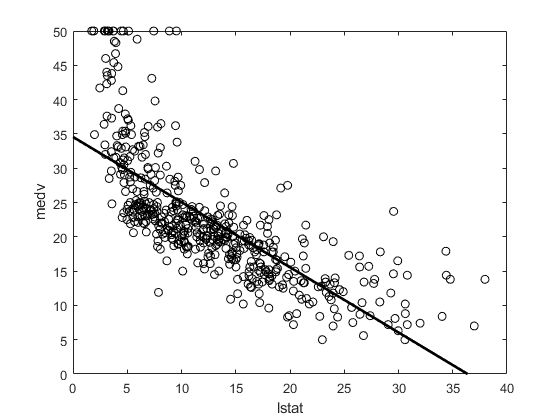

figure
plot(Boston.lstat,Boston.medv,'o','Color','k');
hold on
plot(xlim',predict(lmfit,xlim'),'LineWidth',2,'Color','k');
ylim([0 50])
xlabel 'lstat'
ylabel 'medv'
hold off

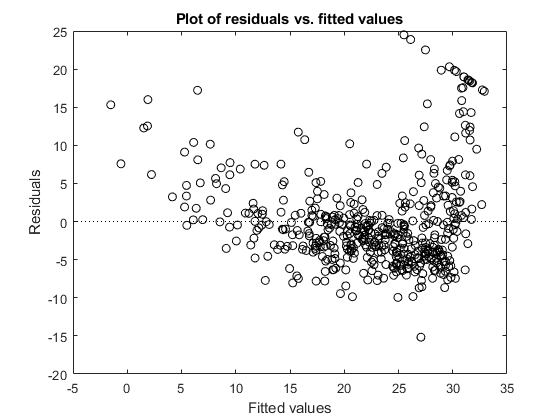

plotResiduals(lmfit,'fitted','Marker','o','Color','k',...
    'ResidualType','Raw');

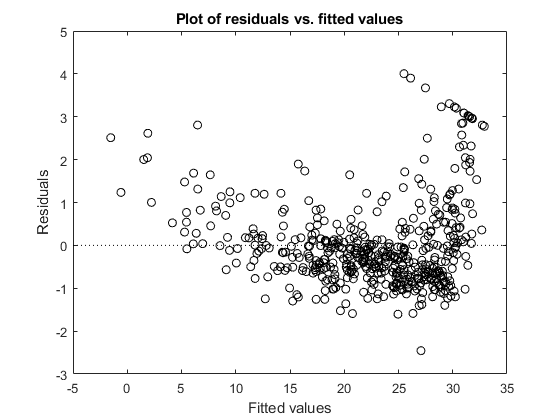

% or
% figure
% plot(lmfit.Fitted,lmfit.Residuals.Raw,'o','Color','k');
% xlabel 'Fitted values'
% ylabel 'Residuals'
plotResiduals(lmfit,'fitted','Marker','o','Color','k',...
    'ResidualType','Studentized');

% or
% figure
% plot(lmfit.Fitted,lmfit.Residuals.Studentized,'o','Color','k');
% xlabel 'Fitted values'
% ylabel 'Studentized'

Plot the leverage values.

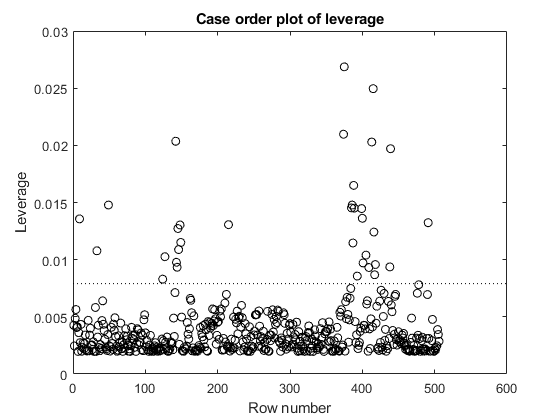

plotDiagnostics(lmfit,'leverage','Marker','o','Color','k');

% or
% figure
% plot((1:length(lmfit.Diagnostics.Leverage)),lmfit.Diagnostics.Leverage,'o','Color','k');
% xlabel 'Index'
% ylabel 'Leverage'
% title 'Case order plot of Leverage'

find(lmfit.Residuals.Studentized == max(lmfit.Residuals.Studentized))

ans = 372

### 3.6.3 Multiple Linear Regression

lmfit = fitlm(Boston,'medv ~ lstat + age')

lmfit = Linear regression model:
    medv ~ 1 + age + lstat

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   ________    ________    _______    ___________

    (Intercept)      33.223     0.73085     45.458    2.9438e-180
    age            0.034544    0.012225     2.8256      0.0049068
    lstat           -1.0321    0.048191    -21.416     8.4196e-73


Number of observations: 506, Error degrees of freedom: 503
Root Mean Squared Error: 6.17
R-squared: 0.551,  Adjusted R-Squared: 0.549
F-statistic vs. constant model: 309, p-value = 2.98e-88

lmfit = fitlm(Boston,'ResponseVar','medv');
lmfit

lmfit = Linear regression model:
    medv ~ 1 + crim + zn + indus + chas + nox + rm + age + dis + rad + tax + ptratio + black + lstat

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________

    (Intercept)        36.459       5.1035      7.1441    3.2834e-12
    crim             -0.10801     0.032865     -3.2865     0.0010868
    zn                0.04642     0.013727      3.3816    0.00077811
    indus            0.020559     0.061496     0.33431       0.73829
    chas               2.6867      0.86158      3.1184      0.001925
    nox               -17.767       3.8197     -4.6513    4.2456e-06
    rm                 3.8099    

fprintf('Computes variance inflation coefficients:\n');

Computes variance inflation coefficients:


array2table(vif(lmfit.Variables{:,lmfit.PredictorNames}),'VariableNames',lmfit.PredictorNames)

ans = 1×13 table
     crim       zn      indus     chas      nox        rm       age       dis       rad       tax      ptratio    black     lstat 
    ______    ______    ______    _____    ______    ______    ______    ______    ______    ______    _______    ______    ______

    1.7922    2.2988    3.9916    1.074    4.3937    1.9337    3.1008    3.9559    7.4845    9.0086    1.7991     1.3485    2.9415


lmfit = fitlm(Boston,'ResponseVar','medv',...
    'PredictorVars',logical(~ismember(Boston.Properties.VariableNames,{'age','medv'})))

lmfit = Linear regression model:
    medv ~ 1 + crim + zn + indus + chas + nox + rm + dis + rad + tax + ptratio + black + lstat

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)       36.437       5.0801     7.1725    2.7155e-12
    crim            -0.10801     0.032832    -3.2897     0.0010747
    zn              0.046334     0.013613     3.4035    0.00071938
    indus           0.020562     0.061433    0.33471       0.73799
    chas               2.689       0.8596     3.1282     0.0018626
    nox              -17.714       3.6793    -4.8144    1.9671e-06
    rm                3.8144      0.40848      9.338   

### 3.6.4 Interaction Terms

lmfit = fitlm(Boston,'medv ~ lstat + age + lstat*age')

lmfit = Linear regression model:
    medv ~ 1 + age*lstat

Estimated Coefficients:
                    Estimate         SE          tStat        pValue  
                   ___________    _________    _________    __________

    (Intercept)         36.089       1.4698       24.553    4.9071e-88
    age            -0.00072086     0.019879    -0.036262       0.97109
    lstat              -1.3921      0.16746      -8.3134    8.7807e-16
    age:lstat         0.004156    0.0018518       2.2443      0.025249


Number of observations: 506, Error degrees of freedom: 502
Root Mean Squared Error: 6.15
R-squared: 0.556,  Adjusted R-Squared: 0.553
F-statistic vs. constant model: 209, p-value = 4.86e-88

% or
% lmfit = fitlm(Boston,'medv ~ lstat*age')

### 3.6.5 Non-linear Transformations of the Predictors

lmfit2 = fitlm(Boston,'medv ~ lstat + lstat^2');

lmfit = fitlm(Boston,'medv ~ lstat');

anova(lmfit,'summary')

ans = 5×5 table
                     SumSq    DF     MeanSq      F         pValue  
                     _____    ___    ______    ______    __________

    Total            42716    505    84.587                        
    Model            23244      1     23244    601.62    5.0811e-88
    Residual         19472    504    38.636                        
    . Lack of fit    17721    453     39.12    1.1394       0.28861
    . Pure error      1751     51    34.333                        


% anova(lmfit)
anova(lmfit2,'summary')

ans = 7×5 table
                     SumSq     DF     MeanSq       F         pValue   
                     ______    ___    ______    _______    ___________

    Total             42716    505    84.587                          
    Model             27369      2     13685     448.51    1.5572e-112
    . Linear          23244      1     23244     761.81     8.819e-103
    . Nonlinear      4125.1      1    4125.1      135.2     7.6301e-28
    Residual          15347    503    30.511                          
    . Lack of fit     13596    452     30.08    0.87613        0.75764
    . Pure error       1751     51    34.333                          


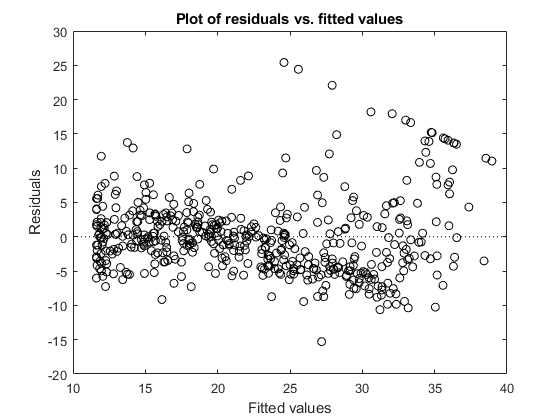

plotResiduals(lmfit2,'fitted','Marker','o','Color','k',...
    'ResidualType','Raw');

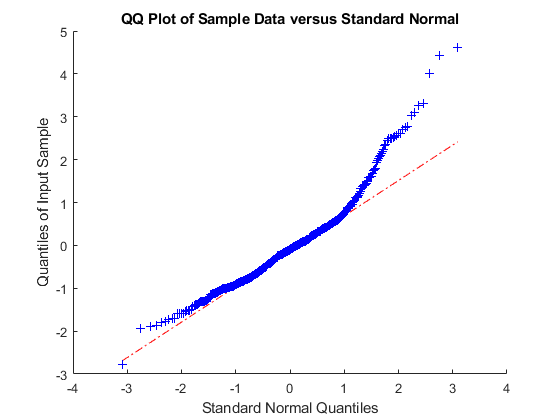

qqplot(lmfit2.Residuals.Standardized)

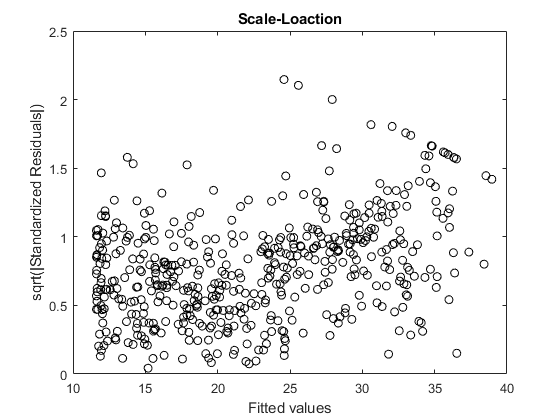

figure
plot(lmfit2.Fitted,(abs(lmfit2.Residuals.Standardized)).^0.5,'o','Color','k');
xlabel 'Fitted values'
ylabel 'sqrt(|Standardized Residuals|)'
title 'Scale-Loaction'

figure
plot(lmfit2.Diagnostics.Leverage,lmfit2.Residuals.Standardized,'o','Color','k');
xlabel 'Leverage'
ylabel 'Standardized Residuals'
title 'Residuals vs Leverage'

Plotting 4 graphs in one figure:

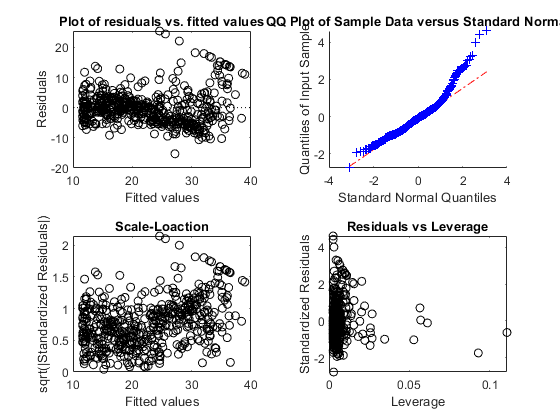

plotFitlm(lmfit2);

lmfit5 = fitlm(Boston,'medv ~ lstat^5')

lmfit5 = Linear regression model:
    medv ~ 1 + lstat + lstat^2 + lstat^3 + lstat^4 + lstat^5

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)          67.7        3.6043     18.783    5.9288e-60
    lstat             -11.991        1.5257    -7.8593    2.3875e-14
    lstat^2            1.2728       0.22317     5.7034    2.0115e-08
    lstat^3         -0.068274      0.014382    -4.7471    2.6985e-06
    lstat^4         0.0017261    0.00041666     4.1426    4.0321e-05
    lstat^5        -1.632e-05    4.4205e-06    -3.6919    0.00024709


Number of observations: 506, Error degrees of freedom: 500
Root Mean Squared Error: 5.2

fitlm(log(Boston.rm),Boston.medv,'ResponseVar','medv',...
    'PredictorVars','log(rm)')

ans = Linear regression model:
    medv ~ 1 + log(rm)

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)    -76.488     5.0277    -15.213    2.7673e-43
    log(rm)         54.055     2.7395     19.732    1.2172e-64


Number of observations: 506, Error degrees of freedom: 504
Root Mean Squared Error: 6.91
R-squared: 0.436,  Adjusted R-Squared: 0.435
F-statistic vs. constant model: 389, p-value = 1.22e-64

### 3.6.6 Qualitative Predictors

Carseats = readtable("Data\Carseats.csv", 'TreatAsEmpty',{'?','NA','N/A'},'ReadRowNames', true);
Carseats.ShelveLoc = categorical(Carseats.ShelveLoc);
Carseats.Urban = categorical(Carseats.Urban);
Carseats.US = categorical(Carseats.US);

Create a *NewCarseats* table by adding 2 columns to the *Carseats* table to represent Interaction Effects *Income:Advertising* and *Price:Age* 

NewCarseats = [Carseats,table(Carseats.Income .* Carseats.Advertising,...
    Carseats.Price .* Carseats.Age,'VariableNames',{'Income:Advertising','Price:Age'})];
lmfit = fitlm(NewCarseats,'ResponseVar','Sales')

lmfit = Linear regression model:
    Sales ~ 1 + CompPrice + Income + Advertising + Population + Price + ShelveLoc + Age + Education + Urban + US + Income:Advertising + Price:Age

Estimated Coefficients:
                           Estimate         SE         tStat       pValue   
                          __________    __________    _______    ___________

    (Intercept)               6.5756        1.0087     6.5185     2.2236e-10
    CompPrice               0.092937     0.0041183     22.567     1.6408e-72
    Income                  0.010894     0.0026044     4.1828     3.5665e-05
    Advertising             0.070246      0.022609      3.107      0.0020299
    Population            0.00015925    0.00036786     0.4329        0.66533
    Price             

[Dummy Variables](https://www.mathworks.com/help/stats/dummy-indicator-variables.html)

unique(NewCarseats.ShelveLoc)

ans = 3×1 categorical array
     Bad 
     Good 
     Medium 


Returns the coding that Matlab uses for the dummy variables.

contrasts(NewCarseats.ShelveLoc)

ans = 3×2 table
              Good    Medium
              ____    ______

    Bad        0        0   
    Good       1        0   
    Medium     0        1   


[Local functions](https://www.mathworks.com/help/matlab/ref/localfunctions.html), used in the main program

function [yPredict, PI] = predictPI(lm, xnew)
    % Calculate prediction intervals of prediction for Linear regression model 
    % source: https://stats.stackexchange.com/questions/69144/calculating-prediction-interval
    yPredict = predict(lm,xnew);
    snewPI = sqrt(lm.MSE * (1 + 1/lm.NumObservations + ...
    (xnew - mean(lm.Variables{:,1:end-1})).^2 / lm.SSE));
    PI = [yPredict - tinv(0.975,lm.DFE)*snewPI, ...
        yPredict + tinv(0.975,lm.DFE)*snewPI];
end
function [V]=vif(X)
    %vif() computes variance inflation coefficients  
    %VIFs are also the diagonal elements of the inverse of the correlation matrix [1], a convenient result that eliminates the need to set up the various regressions
    %[1] Belsley, D. A., E. Kuh, and R. E. Welsch. Regression Diagnostics. Hoboken, NJ: John Wiley & Sons, 1980.
    R0 = corrcoef(X); % correlation matrix
    V=diag(inv(R0))';
end
function plotFitlm(lm)
    % Create 4 plots
    tiledlayout(2,2); % Requires R2019b or later
    nexttile
    plotResiduals(lm,'fitted','Marker','o','Color','k',...
        'ResidualType','Raw');
    nexttile
    qqplot(lm.Residuals.Standardized);
    nexttile
    plot(lm.Fitted,(abs(lm.Residuals.Standardized)).^0.5,'o','Color','k');
    xlabel 'Fitted values'
    ylabel 'sqrt(|Standardized Residuals|)'
    title 'Scale-Loaction'
    nexttile
    plot(lm.Diagnostics.Leverage,lm.Residuals.Standardized,'o','Color','k');
    xlabel 'Leverage'
    ylabel 'Standardized Residuals'
    title 'Residuals vs Leverage'
end
function contrasts(var)
% Set and view the contrasts associated with a factor like function
% contrasts in R
    namesCategorical = cellstr(unique(var));
    array2table([zeros(1,length(namesCategorical)-1); eye(length(namesCategorical)-1)],...
        'VariableNames',namesCategorical(2:end),...
        'RowNames',namesCategorical)
end